## **Przetwarzanie Sygnałów Cyfrowych**

# Próbkowanie sygnałów ciągłych 

## Jan Rosa 410269 AiR

### Ćwiczenie 1 

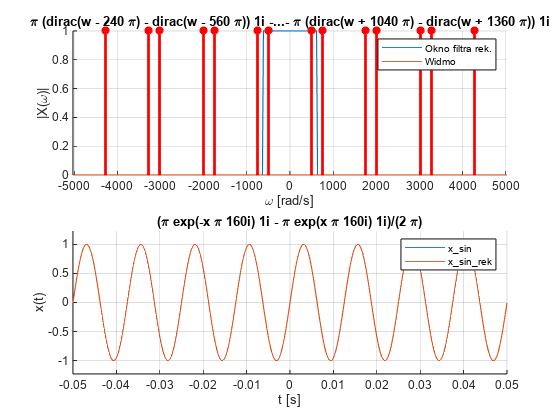

clear all; close all;
syms t x w K
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
s = 4/5; ws = s*wg;
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
   symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
   subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe
FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];
t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];
figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');
subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t);
% syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

### Zadanie 2

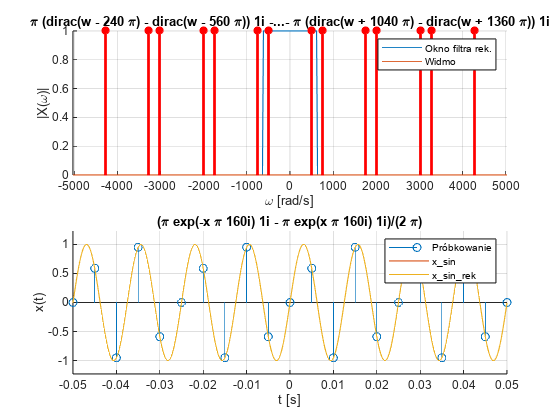

clear all; close all;
syms t x w K
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
s = 4/5; ws = s*wg;
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
   symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
   subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe
FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];
t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];
figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');
subplot(2,1,2); hold on; grid on;
nodex = BND_t(1):1/fp:BND_t(2);
nodey = subs(x_sin, t, nodex);
stem(nodex, nodey);
ezplot(x_sin, BND_t);
% syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('Próbkowanie','x\_sin','x\_sin\_rek');

### Zadanie 3

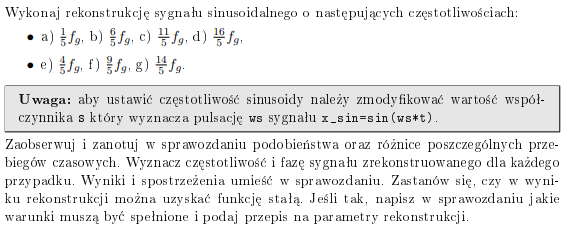

a)

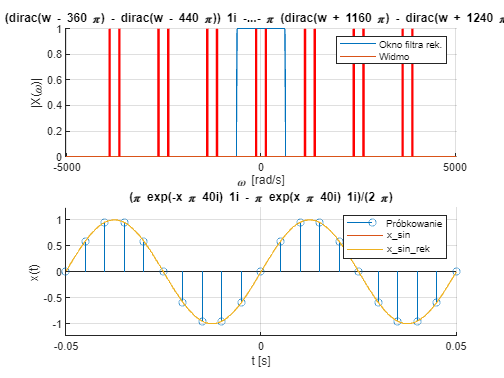

fgplot(1/5)

b)

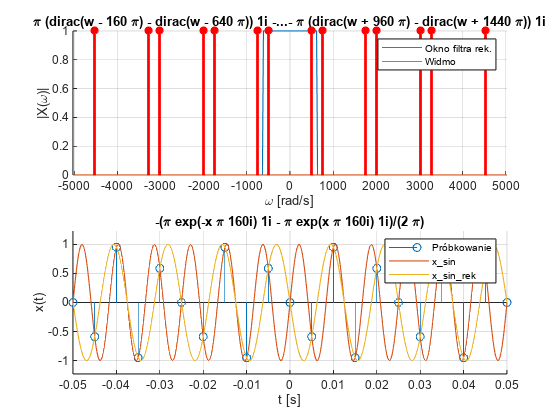

fgplot(6/5)

c)

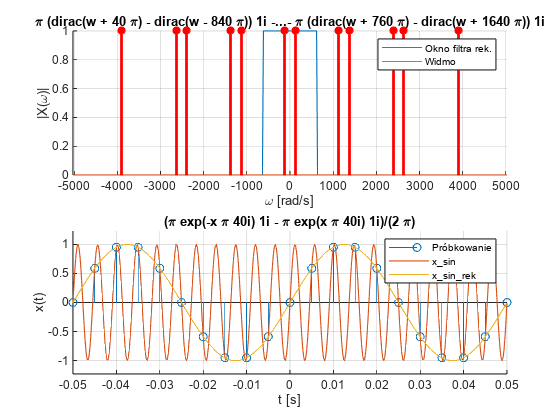

fgplot(11/5)

d)

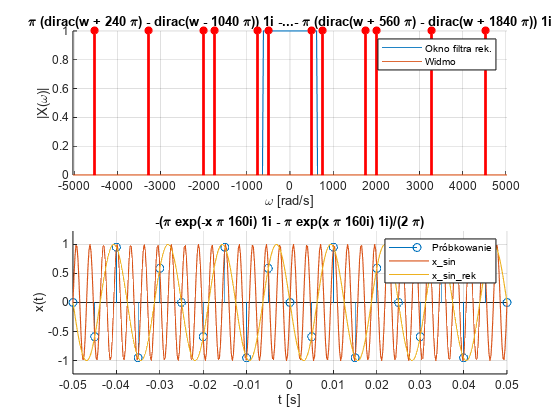

fgplot(16/5)

e)

fgplot(4/5)

f)

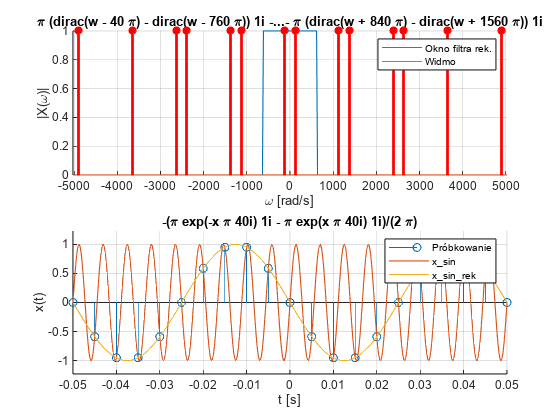

fgplot(9/5)

g)

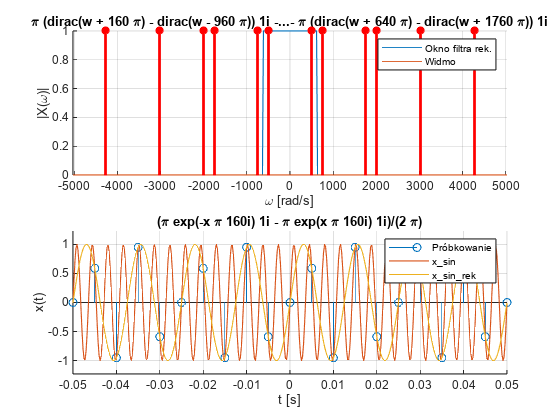

fgplot(14/5)

Najlepeij odtworzona jest funkcja gdy s<1 tj gdy częstotliwość próbkowania jest co najmniej dwa razy większa niż najmniejsza składowa harmoniczna, **Twierdzenie o próbkowaniu**, **twierdzenie Kotelnikowa Shanona.**

Funkcja jest stała wtedy gdy częstowliwość próbkownia pozostaje w stosunku 1/(k+1) do częstotliwości sygnału próbkowaniego gdzie k jest liczbą całkowitą.

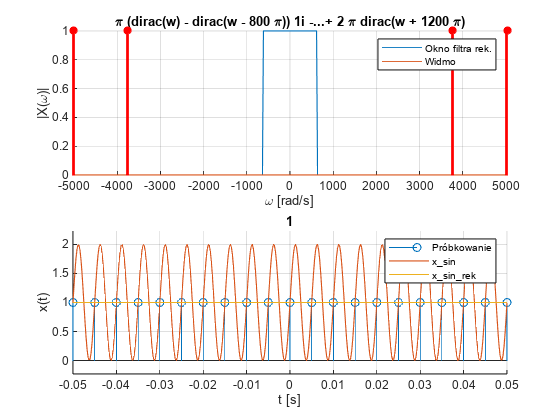

syms t x w K
s = 2;
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
ws = s*wg;
x_sin = sin(ws*t) + 1;
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
   symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
   subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe
FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];
t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];
figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');
subplot(2,1,2); hold on; grid on;
nodex = BND_t(1):1/fp:BND_t(2);
nodey = subs(x_sin, t, nodex);
stem(nodex, nodey);
ezplot(x_sin, BND_t);
% syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('Próbkowanie','x\_sin','x\_sin\_rek');

### Zadanie 4

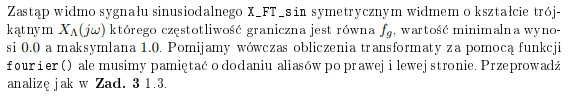

a)

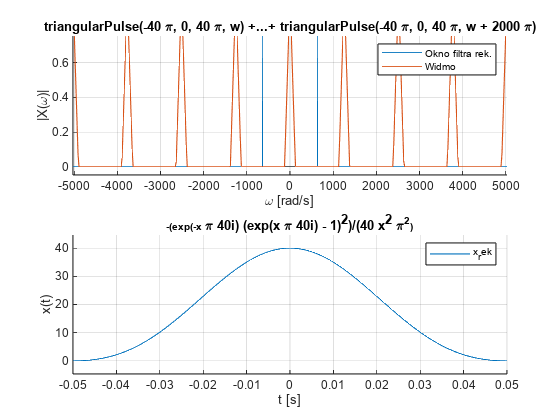

trianwave(1/5)

b)

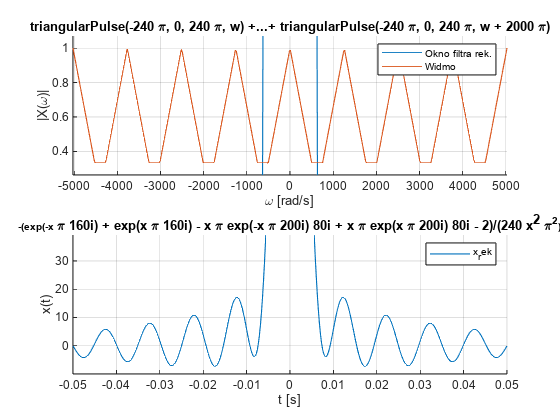

trianwave(6/5)

c)

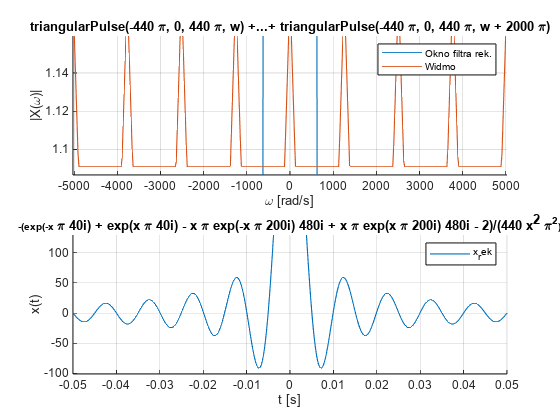

trianwave(11/5)

d)

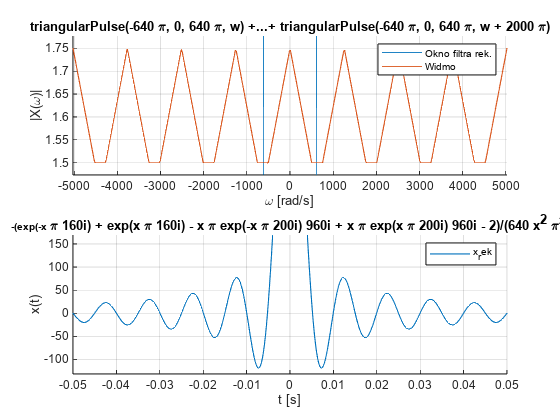

trianwave(16/5)

e)

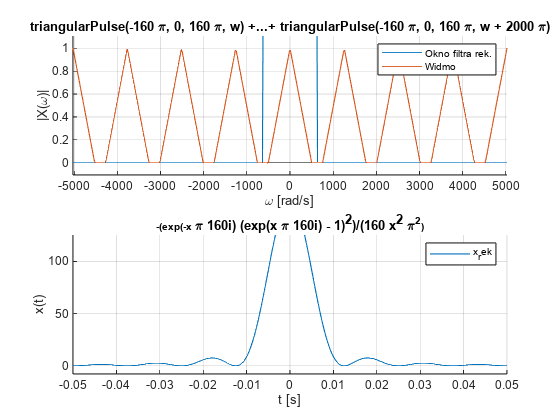

trianwave(4/5)

f)

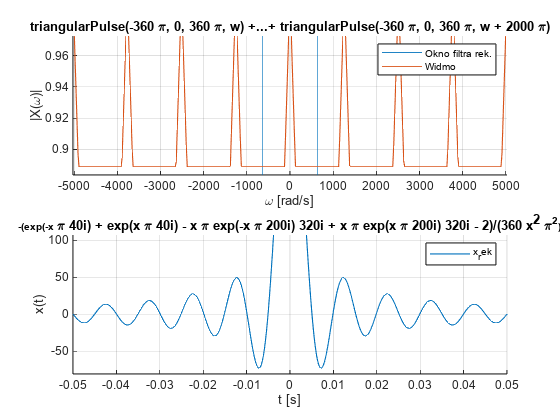

trianwave(9/5)

g)

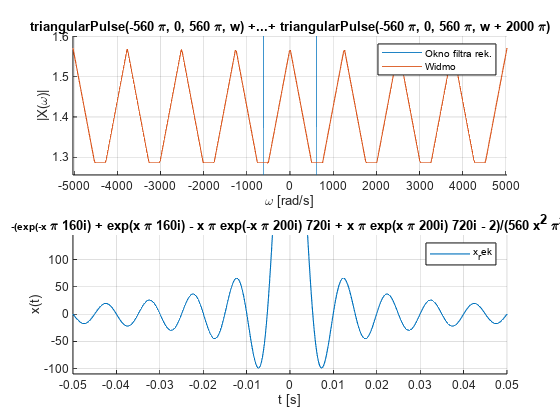

trianwave(14/5)

### Zadanie 5

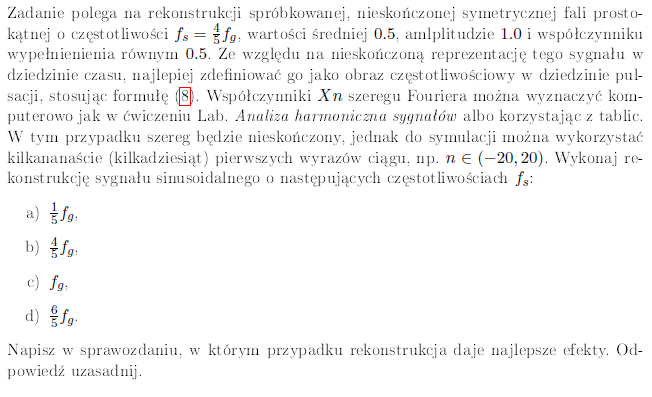

a)

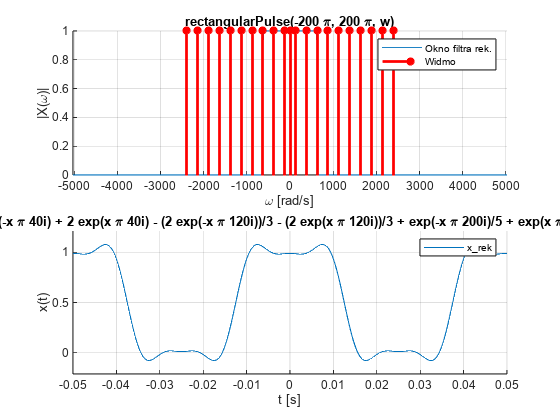

rectwave(1/5)

b)

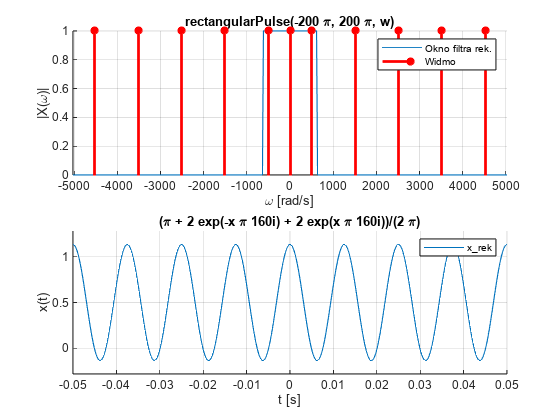

rectwave(4/5)

c)

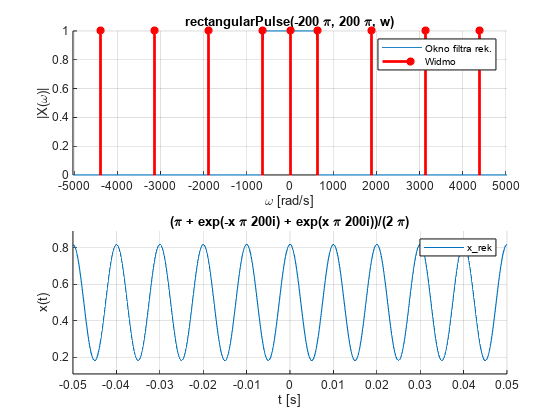

rectwave(1)

d)

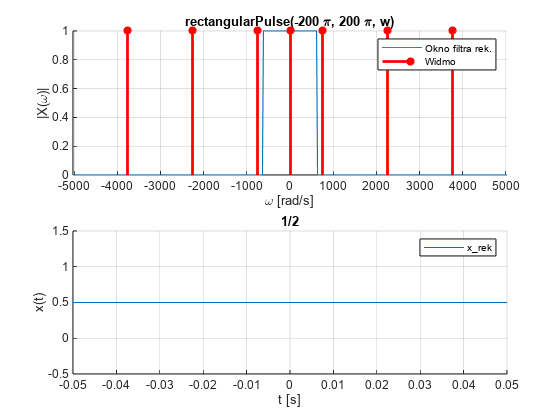

rectwave(6/5)

Rekonstrukcja daje najlepsze efekty gdy okno filtra pokrywa wszystkie składowe częstotliwości sygnału. tj im s mniejsze tym rekonstrukcja lepsza

function [] = fgplot(s)
syms t x w K
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
ws = s*wg;
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
   symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
   subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe
FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];
t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];
figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');
subplot(2,1,2); hold on; grid on;
nodex = BND_t(1):1/fp:BND_t(2);
nodey = subs(x_sin, t, nodex);
stem(nodex, nodey);
ezplot(x_sin, BND_t);
% syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('Próbkowanie','x\_sin','x\_sin\_rek');
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [] = trianwave(s)
syms t x w K
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
ws = s*wg;
x_sin = sym(0);

X_FT_sin_org = triangularPulse(-ws, 0, ws, w);
X_FT_sin = X_FT_sin_org + symsum((subs(X_FT_sin_org, w, w - K*wp ) + subs(X_FT_sin_org, w, w + K*wp)), K , 1, 5);
FILT_FT = 2*rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];
t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];


figure; subplot(2,1,1); hold on; grid on;
title("Trójkątnba transformata")
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
title('Rekonstukcja')
%nodex = BND_t(1):1/fp:BND_t(2);
%nodey = subs(x_sin, t, nodex);
%stem(nodex, nodey);
%ezplot(x_sin, BND_t);
% syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x_rek');
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [] = rectwave(s)
syms t x w K
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
ws = s*wg;
Ts = 1/s/fg;
xTT = rectangularPulse(-Ts/4, Ts/4, t);

NT = 20;
ind = -NT : NT;
X = sym(0);
for n = ind
    Xn = (ws)*int(xTT*exp(-1i*ws*n*t),t, [-1/4*Ts, 3/4*Ts]);
    %Xn to współczynnik
    X = X + sym(Xn)*dirac(w-n*ws);
end

X_FT_sin = X;
x_sin = xTT;

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin_rek, BND_t); % syg. próbkowany
xlabel('t [s]'); ylabel('x(t)')
legend('x\_rek');
end